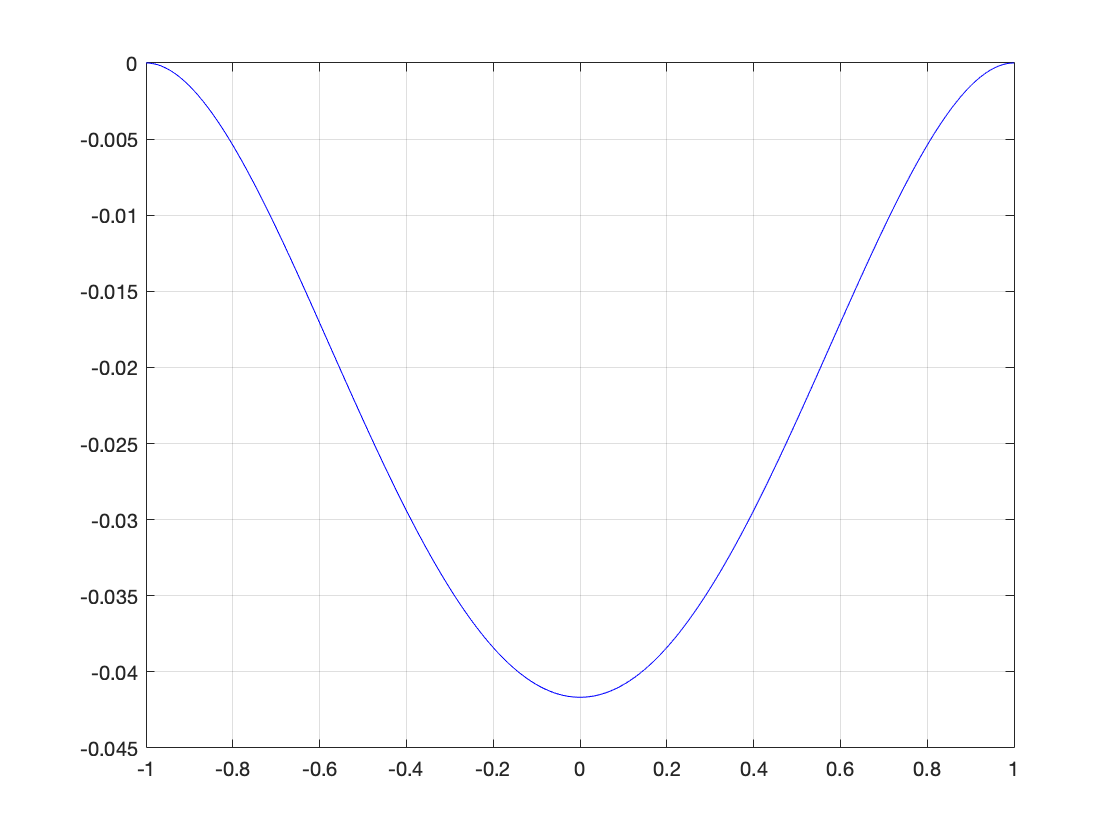

load("stiffness_matrix_1d.mat","A");
load("load_vector_1d.mat","fh");
num_elem = (length(A)-2)/2;
P = interp_mat((length(A)-2)/2+2);
A2 = 1/4*P'*A*P; f2 = P'*fh;
full(A2);

A2(1:2,:) = 0; A2(:,1:2) = 0; A2(1,1) = 1; A2(2,2) = 1;
A2(end-1:end,:) = 0; A2(:,end-1:end) = 0; A2(end-1,end-1) = 1; A2(end,end) = 1;
f2(1:2) = 0; f2(end-1:end) = 0;

u2 = A2\f2;
xs = (-1:4/num_elem:1);

figure
plot(xs, u2(1:2:end), 'b-')
grid on

## Two-grid

load("stiffness_matrix_1d.mat","A");
load("load_vector_1d.mat","fh");
gs_iter = 5; mg_iter = 1;

tic;
uh = tg2(A,fh,gs_iter,mg_iter);
toc;

Elapsed time is 0.061473 seconds.


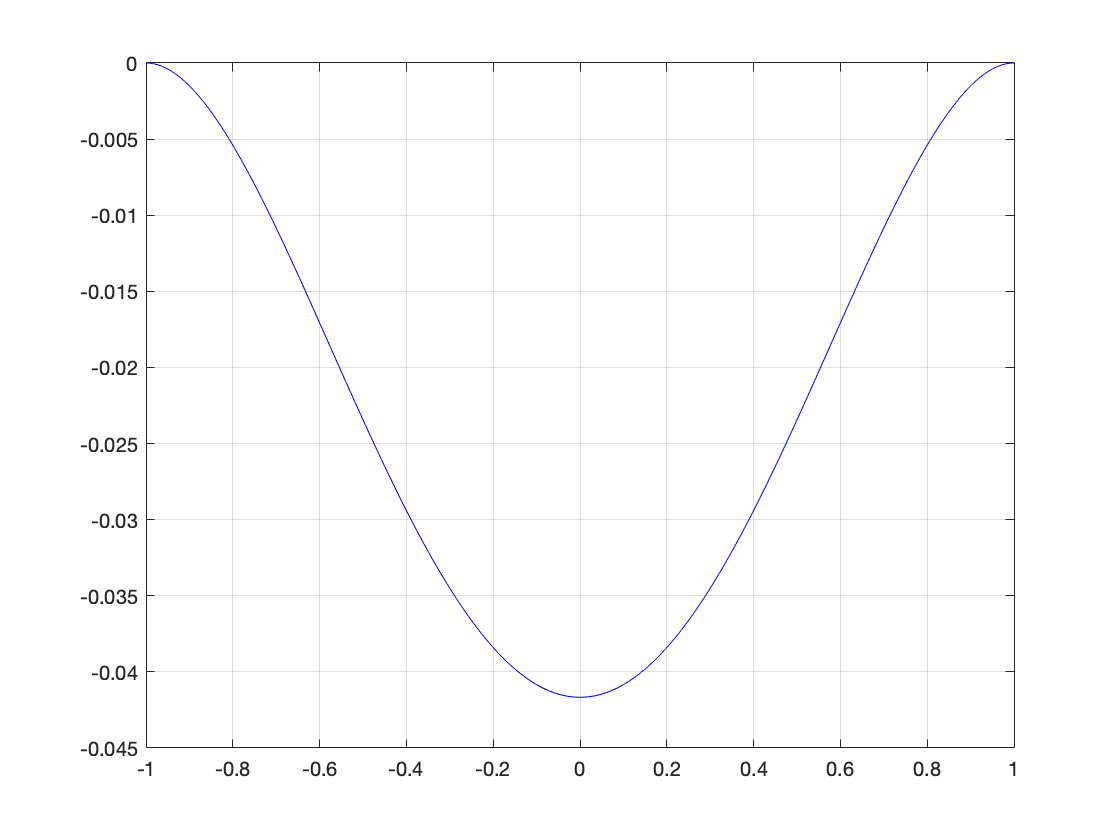

xs = (-1:2/num_elem:1);
figure
plot(xs, uh(1:2:end), 'b-')
grid on

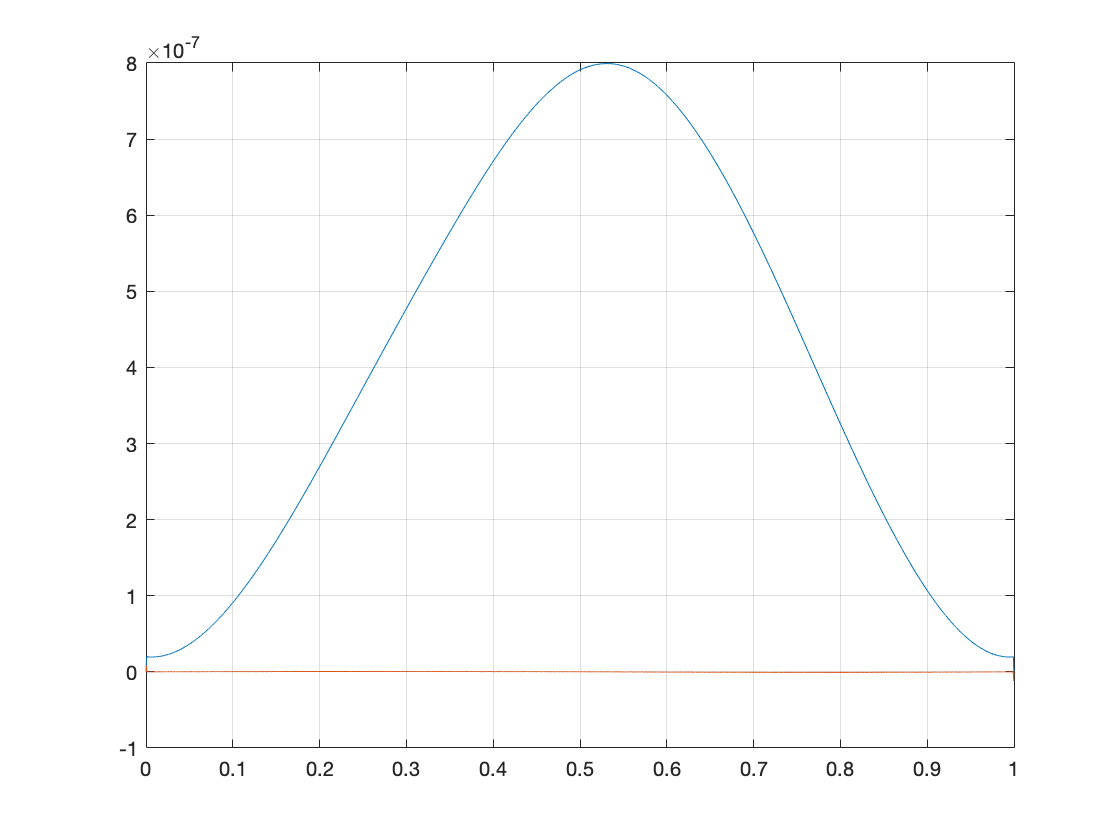

xxs = 0:2/(length(fh)-1):1;
u_true = A\fh;
figure
plot(xxs,u_true(1:2:end)-uh(1:2:end), xxs,u_true(2:2:end)-uh(2:2:end))
grid on

format long
disp(max(abs(u_true-uh)))

     7.992381019991668e-07



function P = interp_mat(N)
    coeffs = [1/2 0 1/2 0; 0 1/2 0 1/2];
    P = zeros(2*N-2,N);
    Nel = (N-2)/2;
    Ncoefs = 4;
    for i=1:2:N
        P(2*i-1,i) = 1; P(2*i,i+1) = 1;
    end
    for i=1:Nel
        indi = 4*i-1; indj = 2*i-1;
        P(indi:indi+1,indj:indj+Ncoefs-1) = coeffs;
    end
    P = sparse(P);
end

function P1d = interp_mat2(N)
    P1 = zeros(2*N-1,N-1);
    for i=1:N-1
        P1(2*i-1:2*i+1,i) = [0.5;1;0.5];
    end
    P1 = sparse(P1);
    P1d = kron(P1,eye(2));
end

function u = gs(A,f,u0,niter)
    L = tril(A,0);
    U = triu(A,1);
    u = u0;
    for i=1:niter
        u = L\(f-U*u);
    end
end

function u_tg = tg(A,fh,gs_iter,mg_iter)
    P = interp_mat((length(A)-2)/2+2);
    
    u0 = zeros(length(fh),1);
    uh = u0;
    
    A2h = 1/4*P'*A*P;
    A2h(1:2,:) = 0; A2h(:,1:2) = 0; A2h(1,1) = 1; A2h(2,2) = 1;
    A2h(end-1:end,:) = 0; A2h(:,end-1:end) = 0; A2h(end-1,end-1) = 1; A2h(end,end) = 1;
    
    for i=1:mg_iter
        uh = gs(A,fh,uh,gs_iter);
        rh = fh - A*uh;

        r2h = P'*rh; r2h(1:2) = 0; r2h(end-1:end) = 0;
        e2h = A2h\r2h;
        
        eh = P*e2h;
        uh = uh + eh;
        uh = gs(A,fh,uh,gs_iter);
    end
    u_tg = uh;
end

function u_tg = tg2(A,fh,gs_iter,mg_iter)
    P = interp_mat2((length(A)-2)/4);
    At = A(3:end-2,3:end-2);
    ft = fh(3:end-2);
    
    u0 = zeros(length(ft),1);
    uh = u0;

    A2h = 1/4*P'*At*P;
    
    for i=1:mg_iter
        uh = gs(At,ft,uh,gs_iter);
        rh = ft - At*uh;

        r2h = P'*rh;
        e2h = A2h\r2h;
        
        eh = P*e2h;
        uh = uh + eh;
        uh = gs(At,ft,uh,gs_iter);
    end
    u_tg = [0;0;uh;0;0];
end